# **Assignment 3**

**EE851 Advanced Digital Communication Systems**

*Instructor: Dr Rizwan Ahmad*

**Submitted by: Mahnoor Anjum **

**Registration Number: 330720**

## **Question 1**

An Internet Service Provider (ISP) uses a compression technique to encode the message before transmitting over the network. Consider that the message contains the following characters with their frequencies as shown in the table. (Note that each character in input message takes 1 bytecompression and the technique used is Huffman Coding,)

 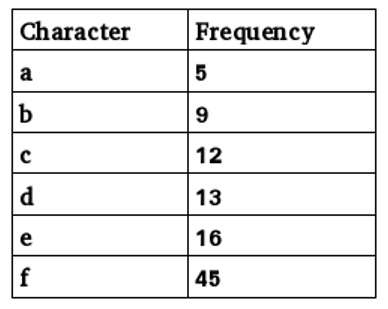

Write a program Huffman coding algorithm to find the code words for the symbols.

### Huffman Coding

Character = ['a' 'b' 'c' 'd' 'e' 'f']';
Frequency = [5 9 12 13 16 45]';
T = table(Character, Frequency);
% T.Probability = T.Frequency / sum(T.Frequency);
T = sortrows(T,'Frequency');
T.State = T.Frequency;
code = ['-' '-' '-' '-' '-' "-"];
T

T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5          5  
        b            9          9  
        c           12         12  
        d           13         13  
        e           16         16  
        f           45         45  


while length(unique(T.State)) ~= 1
T_u = unique(T.State);
[v, idx] = mink(T_u, 2);
temp = T_u(idx(1)) +  T_u(idx(2));
code(T.State == T_u(idx(1))) = append(code(T.State == T_u(idx(1))), 'L');
code(T.State == T_u(idx(2))) = append(code(T.State == T_u(idx(2))), 'R');
T.State(T.State == T_u(idx(1)) | T.State == T_u(idx(2))) = temp;
T
end

T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5         14  
        b            9         14  
        c           12         12  
        d           13         13  
        e           16         16  
        f           45         45  


T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5         14  
        b            9         14  
        c           12         25  
        d           13         25  
        e           16         16  
        f           45         45  


T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5         30  
        b            9         30  
        c           12         25  
        d           13         25  
        e           16         30  
        f           45         45  


T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5         55  
        b            9         55  
        c           12         55  
        d           13         55  
        e           16         55  
        f           45         45  


T = 6×3 table
    Character    Frequency    State
    _________    _________    _____

        a            5         100 
        b            9         100 
        c           12         100 
        d           13         100 
        e           16         100 
        f           45         100 


for i=1:length(code)
    code(i) = replace(code(i), 'L', '0');
    code(i) = replace(code(i), 'R', '1');
    code(i) = reverse(code(i));
    disp([T.Character(i) code(i)]);
end

    "a"    "1100-"

    "b"    "1101-"

    "c"    "100-"

    "d"    "101-"

    "e"    "111-"

    "f"    "0-"



## **Question 2 **

A Telecom company uses a compression technique to encode the source message before transmitting it over the network Consider that the source emits six symbols (x1,x2, x3...x6) with probabilities 0.3, 0.25, 0.2, 0.1, 0.1 and 0.05, respectively. Construct a Shannon-Fano code for this source. 

### Shannon Fano Coding Results 

Character = ["x1" 'x2' 'x3' 'x4' 'x5' 'x6']';
Probability = [0.3 0.25 0.2 0.1 0.1 0.05]';
T = table(Character, Probability)

T = 6×2 table
    Character    Probability
    _________    ___________

      "x1"           0.3    
      "x2"          0.25    
      "x3"           0.2    
      "x4"           0.1    
      "x5"           0.1    
      "x6"          0.05    


code = containers.Map;
for i = 1:length(T.Character)
           code(T.Character(i)) = '';
end
% Function at EOF
shannonFanoAlgo(T, code)
keys(code)

ans = 1×6 cell array
    {'x1'}    {'x2'}    {'x3'}    {'x4'}    {'x5'}    {'x6'}


values(code)

ans = 1×6 cell array
    {'00'}    {'01'}    {'10'}    {'110'}    {'1110'}    {'1111'}


## **Question 3**

You are required to investigate the properties of a simple channel code (Turbo and Convolutional code) by using MATLAB. You will encode (using Turbo and Convolutional coders) and decode (using Viterbi algorithm). Consider that 10000 binary bits sequence is transmitted with and without transmission errors. Channel coding adds extra data bits to make the transmission of data more robust to disturbances present on the transmission channel. The purpose of this assignment is to build a simple coder to reduce errors in a noisy binary channel. In this assignment, Turbo and Convolutional coding will be applied to reduce the transmission errors. Examine the length of the transmission sequence before and after channel coding. Relate that to the code parameters (n and k)? How many consecutive errors can your channel code correct?

**Hints**

- **This code has *****K***** = 2, *****k***** = 2, *****n***** = 3, and a rate of 2/3.**

- **The generator functions for this code are *****g*****1 = [1011], *****g*****2 = [1101], *****g*****3 = [1010]**

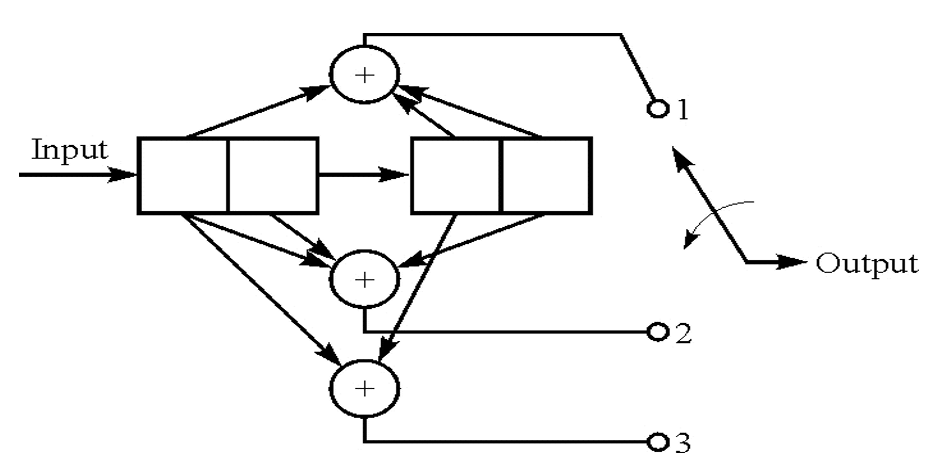

#### State table of the Convolutional Code

m4 = [0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 ]';
m3 = [0 0 1 1 0 0 1 1 0 0 1 1 0 0 1 1 ]';
m2 = [0 0 0 0 1 1 1 1 0 0 0 0 1 1 1 1 ]';
m1 = [0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 ]';
T  = table(m1, m2, m3, m4);
T.x1 = mod(T.m1+T.m3+T.m4,2);
T.x2 = mod(T.m1+T.m3+T.m4,2);
T.x3 = mod(T.m1+T.m3,2);
T

T = 16×7 table
    m1    m2    m3    m4    x1    x2    x3
    __    __    __    __    __    __    __

    0     0     0     0     0     0     0 
    0     0     0     1     1     1     0 
    0     0     1     0     1     1     1 
    0     0     1     1     0     0     1 
    0     1     0     0     0     0     0 
    0     1     0     1     1     1     0 
    0     1     1     0     1     1     1 
    0     1     1     1     0     0     1 
    1     0     0     0     1     1     1 
    1     0     0     1     0     0     1 
    1     0     1     0     0     0     0 
    1     0     1     1     1     1     0 
    1     1     0     0     1     1     1 
    1     1     0     1     0     0     1 
    1     1     1     0     0     0     0 
    1     1    

#### A from-scratch Implementation of the Convolutional Code

% An example of encoding 10010 
m = [1 1 1 1 1 1];
transmissionOrder = fliplr(m);
K = 2; k=2; n=3;
output = [];
temp = zeros(1, length(m));
stream = cat(2, temp, transmissionOrder);
for i=1:4
    temp = circshift(stream,i*k);
    disp("     m1    m2    m3    m4 ");
    disp(temp(1:4));
    b1 = T.x1(T.m1 == temp(1) & T.m2 == temp(2) & T.m3 == temp(3) & T.m4 == temp(4));
    b2 = T.x2(T.m1 == temp(1) & T.m2 == temp(2) & T.m3 == temp(3) & T.m4 == temp(4));
    b3 = T.x3(T.m1 == temp(1) & T.m2 == temp(2) & T.m3 == temp(3) & T.m4 == temp(4));
    output = [output b3 b2 b1];
end

     m1    m2    m3    m4 


     1     1     0     0



     m1    m2    m3    m4 


     1     1     1     1



     m1    m2    m3    m4 


     1     1     1     1



     m1    m2    m3    m4 


     0     0     1     1



output = fliplr(output)

output =      0     0     1     1     1     0     1     1     0     1     1     1


length(output)

ans = 12

- **For Turbo Encoder use the same convolutional coder twice and use interleaver (Interleaver is used to provide randomness to the input sequences or to improver burst error correction capacity**.**) for the second coder as shown in block diagram below.**

#### **A from Scratch Implementation of Turbo Code**

N = 10000;
interlvrindices = randperm(N);
data = randi([0 1],N,1);
trellis = poly2trellis([2 2], [3 2 3;1 3 0]);
hConEnc = comm.ConvolutionalEncoder(trellis);
temp1 = step(hConEnc, data);
temp1 = reshape(temp1, [],3);
temp2 = step(hConEnc, data(interlvrindices));
temp2 = reshape(temp2, [],3);

encodedDataT = [];
temp = reshape(data, [],2);
for i=1:length(temp1)
    encodedDataT = cat(2,encodedDataT, temp(i,:));
    encodedDataT = cat(2,encodedDataT, temp1(i,:));
    encodedDataT = cat(2,encodedDataT, temp2(i,:));
end

length(encodedDataT)

ans = 40000

Theoratical output stream length: 

coding_rate = 2/8;
length(data)/coding_rate

ans = 40000

**Code rate 2/8 **

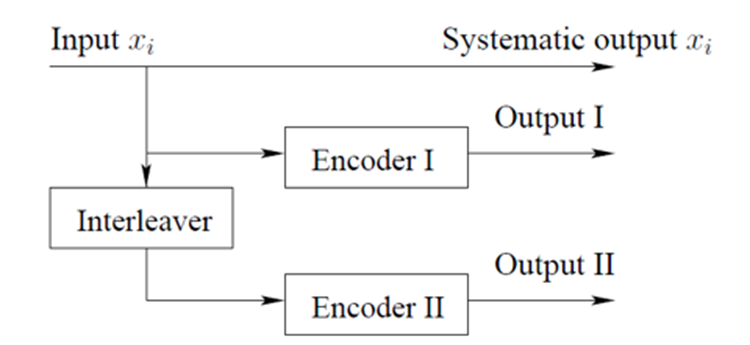

**Case 1 (without transmission errors)**

- Generate 10000 bits binary sequence.

- Encode the data using Turbo and Convolutional code.

- Consider the channel is ideal.

- Decode the encoded data using Viterbi.

- Compare with the input data sequence.

- Plot the BER for both Turbo and convolutional coders

### Ideal Channel

#### Trellis Structure Definition

K = 2; k=2; n=3;
g1 = [1 0 1 1]; g1 = bi2oct(g1);
g2 = [1 1 0 1]; g2 = bi2oct(g2);
g3 = [1 0 1 0]; g3 = bi2oct(g3);
pPatternVec = [0 0 0 1 1 1]';
trellisT = poly2trellis(4, [g1 g2 g3])

trellisT = struct with fields:
     numInputSymbols: 2
    numOutputSymbols: 8
           numStates: 8
          nextStates: [8×2 double]
             outputs: [8×2 double]


% trellis = poly2trellis([2 2], [3 2 3;1 3 0])

#### Channel Definitions 

N = 10000;
interlvrindices = randperm(N);

hConEnc = comm.ConvolutionalEncoder(trellisT, ...
    'PuncturePatternSource','Property', ...
    'PuncturePattern',pPatternVec);
hTurEnc = comm.TurboEncoder(trellisT, interlvrindices);
hcDec = comm.ViterbiDecoder(trellisT, 'InputFormat','Hard', ...
    'PuncturePatternSource','Property', ...
    'PuncturePattern',pPatternVec);
htDec = comm.TurboDecoder(trellisT, interlvrindices);
hcError  = comm.ErrorRate("ReceiveDelay", hcDec.TracebackDepth);
htError = comm.ErrorRate;

#### BER and Total Error count over 100 iterations in an Ideal Channel

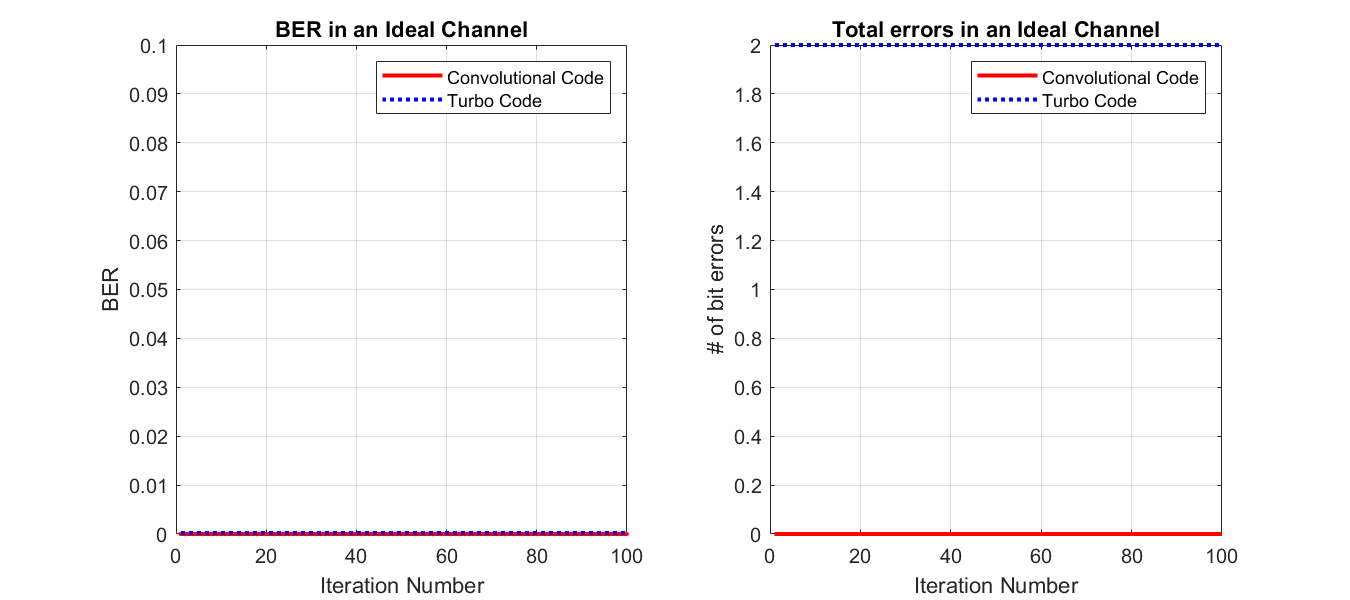

iters = 100;
BERT = zeros(1,iters);
BERC = zeros(1,iters);
data = randi([0 1],N,1);
totalErrsC = zeros(1,iters);
totalErrsT = zeros(1,iters);
for i=1:iters
    encodedData = step(hConEnc, data);
    receivedBits = step(hcDec, encodedData);
    errorsC = step(hcError, data, receivedBits);
    encodedData = step(hTurEnc, data);
    receivedBits = step(htDec, encodedData);
    errorsT = step(htError, data, receivedBits);
    BERC(i) = errorsC(1);
    BERT(i) = errorsT(1);
    totalErrsT(i) = errorsT(2);
    totalErrsC(i) = errorsC(2);
    reset(hcError);
    reset(htError);
end

figure('Renderer', 'painters', 'Position', [10 10 900 400]);
subplot(121), hold on, grid on, box on; 
plot(BERC, "r.-", "LineWidth",2);
plot(BERT, "b:", "LineWidth",2);
legend("Convolutional Code", "Turbo Code"); 
xlabel("Iteration Number"); ylabel("BER");
ylim([0,0.1]);
title("BER in an Ideal Channel");
subplot(122), hold on, grid on, box on; 
plot(totalErrsC, "r-", "LineWidth",2);
plot(totalErrsT, "b:", "LineWidth",2);
legend("Convolutional Code", "Turbo Code"); 
xlabel("Iteration Number"); ylabel("# of bit errors");
title("Total errors in an Ideal Channel");

**Case 2 (with transmission errors)**

- Generate 10000 bits binary sequence.

- Encode the data using Turbo and Convolutional code.

- Consider the channel is AWGN or generate a 10000 bits binary array for error. Pass the encoded data and without encoded data through channel  

- Decode the encoded data using Viterbi.

- Compare with the input data sequence.

- Plot the BER for both Turbo and convolutional coders

### Noisy Channel

#### Trellis Structure Definition

clear;
K = 2; k=2; n=3;
g1 = [1 0 1 1]; g1 = bi2oct(g1);
g2 = [1 1 0 1]; g2 = bi2oct(g2);
g3 = [1 0 1 0]; g3 = bi2oct(g3);
pPatternVec = [0 0 0 1 1 1]';
trellis = poly2trellis(4, [g1 g2 g3])

trellis = struct with fields:
     numInputSymbols: 2
    numOutputSymbols: 8
           numStates: 8
          nextStates: [8×2 double]
             outputs: [8×2 double]


#### Channel Definitions

N = 1000;
interlvrindices = randperm(N);
hConEnc = comm.ConvolutionalEncoder(trellis, ...
                                    'PuncturePatternSource','Property', ...
                                    'PuncturePattern', pPatternVec);
hTurEnc = comm.TurboEncoder(trellis, interlvrindices);

hChan = comm.AWGNChannel('NoiseMethod', ...
                            'Signal to noise ratio (SNR)',...
                            'SNR',8);
hcDec = comm.ViterbiDecoder(trellis, 'InputFormat','Hard', ...
                                    'PuncturePatternSource','Property',...
                                    'PuncturePattern',pPatternVec);
htDec = comm.TurboDecoder(trellis, interlvrindices);
hcError  = comm.ErrorRate('ReceiveDelay',hcDec.TracebackDepth);
htError  = comm.ErrorRate;
hrError  = comm.ErrorRate('ReceiveDelay',hcDec.TracebackDepth);

#### BER and Total Error Count over 100 iterations with SNR 8dB

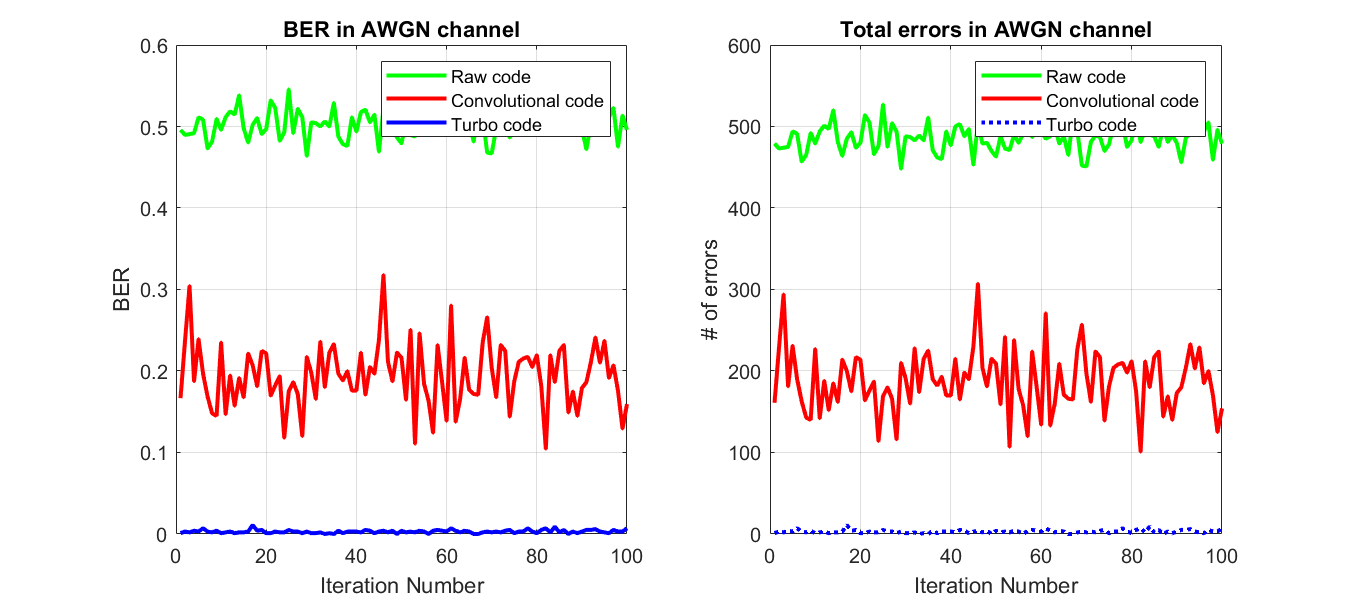

iters = 100;
BERT = zeros(1,iters);
BERC = zeros(1,iters);
BERR = zeros(1,iters);

totalErrsC = zeros(1,iters);
totalErrsT = zeros(1,iters);
totalErrsR = zeros(1,iters);
for i=1:iters
    data = randi([0 1],N,1);
    rawSent = data;
    receivedSignal = step(hChan, rawSent);
    receivedBits = double(receivedSignal>0);
    errorsR = step(hrError, data, receivedBits);
    encodedData = step(hConEnc, data);
    receivedSignal = step(hChan, encodedData);
    receivedSignal = double(receivedSignal>0.5);
    receivedBits = step(hcDec, receivedSignal);
    errorsC = step(hcError, data, receivedBits);
    encodedData = step(hTurEnc, data);
    receivedSignal = step(hChan, encodedData);
    receivedBits = step(htDec, receivedSignal);
    errorsT = step(htError, data, receivedBits);
    reset(htError); % reset(htChan); reset(htDec); reset(hTurEnc);
    reset(hcError); % reset(hcChan); reset(hcDec); reset(hConEnc);
    reset(hrError); % reset(hrChan); 
    BERR(i) = errorsR(1);
    BERT(i) = errorsT(1);
    BERC(i) = errorsC(1);
    totalErrsT(i) = errorsT(2);
    totalErrsC(i) = errorsC(2);
    totalErrsR(i) = errorsR(2);
end
figure('Renderer', 'painters', 'Position', [10 10 900 400]),
subplot(121); hold on, grid on, box on; 
plot(BERR, "g", "LineWidth",2);
plot(BERC, "r", "LineWidth",2);
plot(BERT, "b", "LineWidth",2);
xlabel("Iteration Number"); ylabel("BER");
legend("Raw code", "Convolutional code", "Turbo code");
title("BER in AWGN channel");
subplot(122); hold on, grid on, box on; 
plot(totalErrsR, "g", "LineWidth",2);
plot(totalErrsC, "r-", "LineWidth",2);
plot(totalErrsT, "b:", "LineWidth",2);
xlabel("Iteration Number"); ylabel("# of errors");
legend("Raw code", "Convolutional code", "Turbo code");
title("Total errors in AWGN channel");

#### BER with respect to SNR (dB)

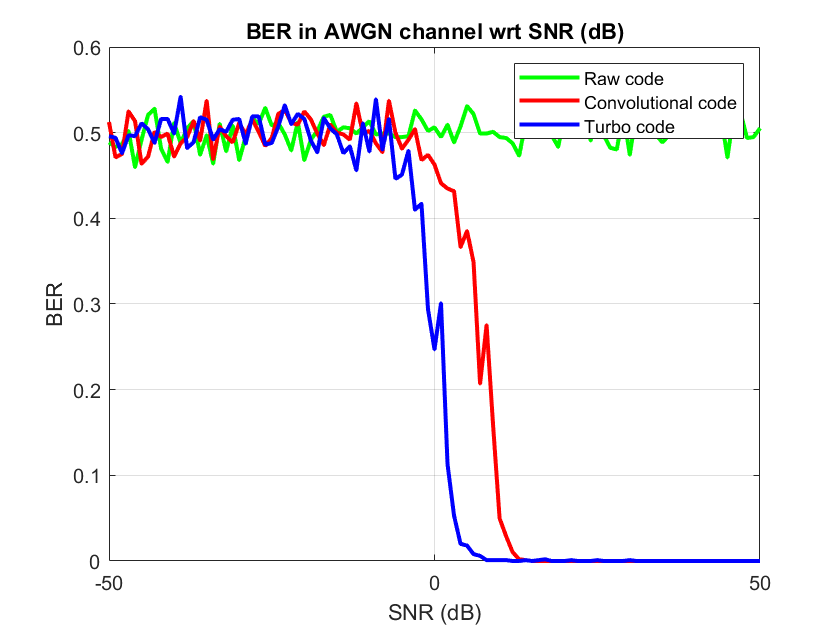

snr = -50:1:50;
BERT = zeros(1,length(snr));
BERC = zeros(1,length(snr));
BERR = zeros(1,length(snr));

for i=1:length(snr)
    hChan = comm.AWGNChannel('NoiseMethod', ...
                            'Signal to noise ratio (SNR)',...
                            'SNR',snr(i));
    data = randi([0 1],N,1);
    rawSent = data;
    receivedSignal = step(hChan, rawSent);
    receivedBits = double(receivedSignal>0);
    errorsR = step(hrError, data, receivedBits);
    encodedData = step(hConEnc, data);
    receivedSignal = step(hChan, encodedData);
    receivedSignal = double(receivedSignal>0.5);
    receivedBits = step(hcDec, receivedSignal);
    errorsC = step(hcError, data, receivedBits);
    encodedData = step(hTurEnc, data);
    receivedSignal = step(hChan, encodedData);
    receivedBits = step(htDec, receivedSignal);
    errorsT = step(htError, data, receivedBits);
    reset(htError); % reset(htChan); reset(htDec); reset(hTurEnc);
    reset(hcError); % reset(hcChan); reset(hcDec); reset(hConEnc);
    reset(hrError); % reset(hrChan); 
    BERR(i) = errorsR(1);
    BERT(i) = errorsT(1);
    BERC(i) = errorsC(1);
end
figure(), hold on, grid on, box on; 
plot(snr,BERR, "g", "LineWidth",2);
plot(snr,BERC, "r", "LineWidth",2);
plot(snr,BERT, "b", "LineWidth",2);
xlabel("SNR (dB)"); ylabel("BER");
legend("Raw code", "Convolutional code", "Turbo code");
title("BER in AWGN channel wrt SNR (dB)");

**Interleaver**

One of the simplest procedures for doing interleaving the data is to divide the whole transmitted binary sequence data into two arrays. The first array contains the first 50 % of the binary sequence data and the last 50 % of the binary sequence data containing the second array. Make a new data array that contains one element of the first array after this second element of the second array. The new data array is called the interleaved array of the data.

## Shannon Fano Coding Function

function res = shannonFanoAlgo(T, code)
    if height(T) ~= 1
        if height(T) > 2
            T.Temp = cumsum(T.Probability);
            [~,idx] = (min(abs(T.Temp - (0.5))));
        else 
            idx = 1;
        end
        for i = 1:idx
            code(T.Character(i)) = strcat(code(T.Character(i)), '0');
        end
        for i = idx+1:height(T)
            code(T.Character(i)) = strcat(code(T.Character(i)), '1');
        end
        T1 = T(1:idx,:);
        T2 = T(idx+1:height(T),:);
        T2.Probability(:) = T2.Probability(:)/sum(T2.Probability(:));
        T1.Probability(:) = T1.Probability(:)/sum(T1.Probability(:));
        shannonFanoAlgo(T1, code);
        shannonFanoAlgo(T2, code);
    end
end


## Helper Functions

function out = bi2oct(g1)
g1 = bi2de(g1);
g1 = dec2base(g1, 8);
out = str2num(g1);
end


## **Note**

The matlab turbo codes implementation does not allow trellis structures with K not equal to 1. 

- Reference: [https://www.mathworks.com/help/comm/ref/comm.turboencoder-system-object.html](https://www.mathworks.com/help/comm/ref/comm.turboencoder-system-object.html)

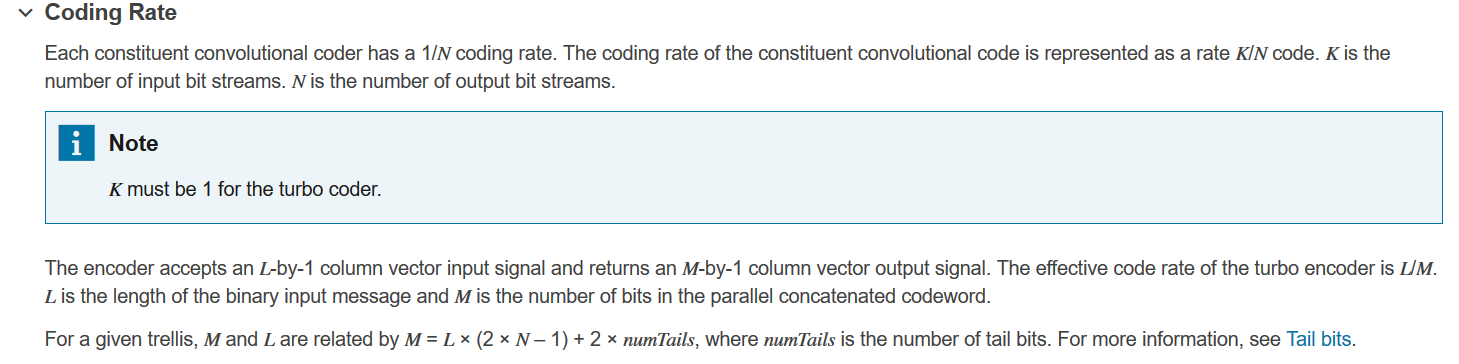

- Two implementations have been presented in the assignment; an implementation mimicing the block diagram, made from sub-components for turbo codes, and an implementation using the communication toolbox components, with an input step of 1 instead of 2, thus implementing convolutional encoder blocks of code-rate 1/3.